In this notebook, for each arm design we will sweep thorugh a variety of pressure and loading configurations in order to plot how each arm's workspace under load. Here, we define "workspace" to mean the arc of furthest reaching. Thus, for the two muscle arm, we will sweep through actuator 1 being pressurized, and then actuator 2 being pressurized. For the antagonist am, this will be when an antagonistic pair works together.

%% Global variables
% Define baseline arm geometry
rho_outer_base = 0.06;
rho_inner_base = 0.01;
rho_outer_tip = 0.02;
rho_inner_tip = 0.01;
l_0 = 0.5;
N_seg = 6;

% Generate workspace plot for a single arm design
straight_muscle_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_seg, rho_outer_base, l_0);
straight_muscle_arm.set_mechanics(GinaMuscleMechanics(l_0));

max_p = 100;
max_load = 4; % Newtons

N_loads = 10;
N_p = 10;

loads = linspace(0, max_load, N_loads);
pressures = linspace(0, max_p, N_p);

cell_g_circ_right = cell(N_loads, N_p);
cell_tip_poses = cell(N_loads, N_p);
tic;
for i = 1 : length(loads)
    Q_i = [0; -loads(i); 0];
    for j = 1 : length(pressures)
        p_j = [0; pressures(j)];
        cell_g_circ_right{i, j} = straight_muscle_arm.solve_equilibrium_gina(p_j, Q_i, "frame", "World");
        cell_tip_poses{i, j} = Pose2.vee(straight_muscle_arm.get_tip_pose());
    end
end
toc

Elapsed time is 58.053807 seconds.


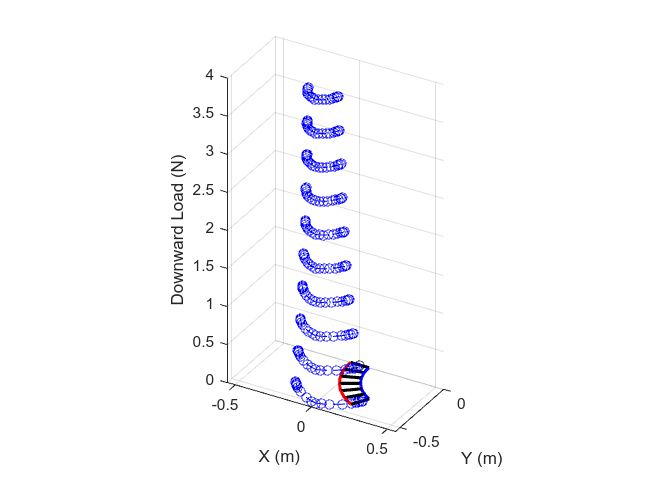

ax = axes(figure());
hold on
for i = 1 : size(cell_tip_poses, 1)
    tip_poses_i = [cell_tip_poses{i, :}];
    load_i = loads(i);
    v_load_i = load_i * ones(1, size(tip_poses_i, 2));
    plot3(ax, tip_poses_i(1, :), tip_poses_i(2, :), v_load_i, 'bo--');
    plot3(ax, -tip_poses_i(1, :), tip_poses_i(2, :), v_load_i, 'bo--');
end
plot3(ax, 0, 0, 0, 'ko')
grid on
view(ax, 30, 30)


straight_muscle_arm.solve_equilibrium_gina([0; 80], [0; 0; 0]);
Plotter2D.plot_arm_series(straight_muscle_arm, ax);

axis auto
ylim(ax, [-0.55, 0])
xlim(ax, [-0.55, 0.55]);
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Downward Load (N)")
daspect([1, 1, 2])

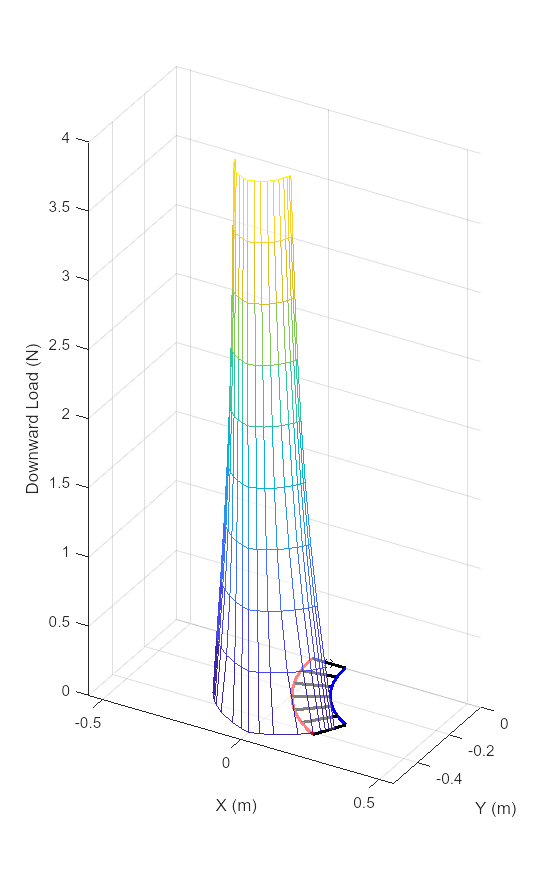

ax = axes(figure("Position", [0, 0, 500, 800]));
hold on
X = zeros(N_loads, N_p);
Y = zeros(N_loads, N_p);
Z = zeros(N_loads, N_p);
for i = 1 : N_loads
    load_i = loads(i);
    for j = 1 : N_p
        tip_pose_ij = cell_tip_poses{i, j};
        X(i, j) = tip_pose_ij(1);
        Y(i, j) = tip_pose_ij(2);
        Z(i, j) = load_i;
    end
end
mesh(X, Y, Z, "facealpha", 0.5)
mesh(-X, Y, Z, "facealpha", 0.5)
plot3(ax, 0, 0, 0, 'ko')
grid on
view(ax, 30, 30)


straight_muscle_arm.solve_equilibrium_gina([0; 80], [0; 0; 0]);
Plotter2D.plot_arm_series(straight_muscle_arm, ax);

axis auto
ylim(ax, [-0.55, 0])
xlim(ax, [-0.55, 0.55]);
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Downward Load (N)")
daspect([1, 1, 2])